# Driven Damped Pendulum

$m L^{2} \ddot{\phi}=-b L^{2} \dot{\phi}-m g L \sin \phi+L F(t)$       ***where  ***    $F(t)=F_{\mathrm{o}} \cos (\omega t)$


$$\ddot{\phi}+\frac{b}{m} \dot{\phi}+\frac{g}{L} \sin \phi=\frac{F_{\mathrm{o}}}{m L} \cos \omega t$$
       
$$\to$$
      
$$\frac{b}{m}=2 \beta$$
        
$$\frac{g}{L}=\omega_{o}^{2}$$
       
$$\gamma=\frac{F_{\mathrm{o}}}{m L \omega_{\mathrm{o}}^{2}}=\frac{F_{\mathrm{o}}}{m g}$$



$$\ddot{\phi}+2 \beta \dot{\phi}+\omega_{0}^{2} \sin \phi=\gamma \omega_{0}^{2} \cos \omega t$$


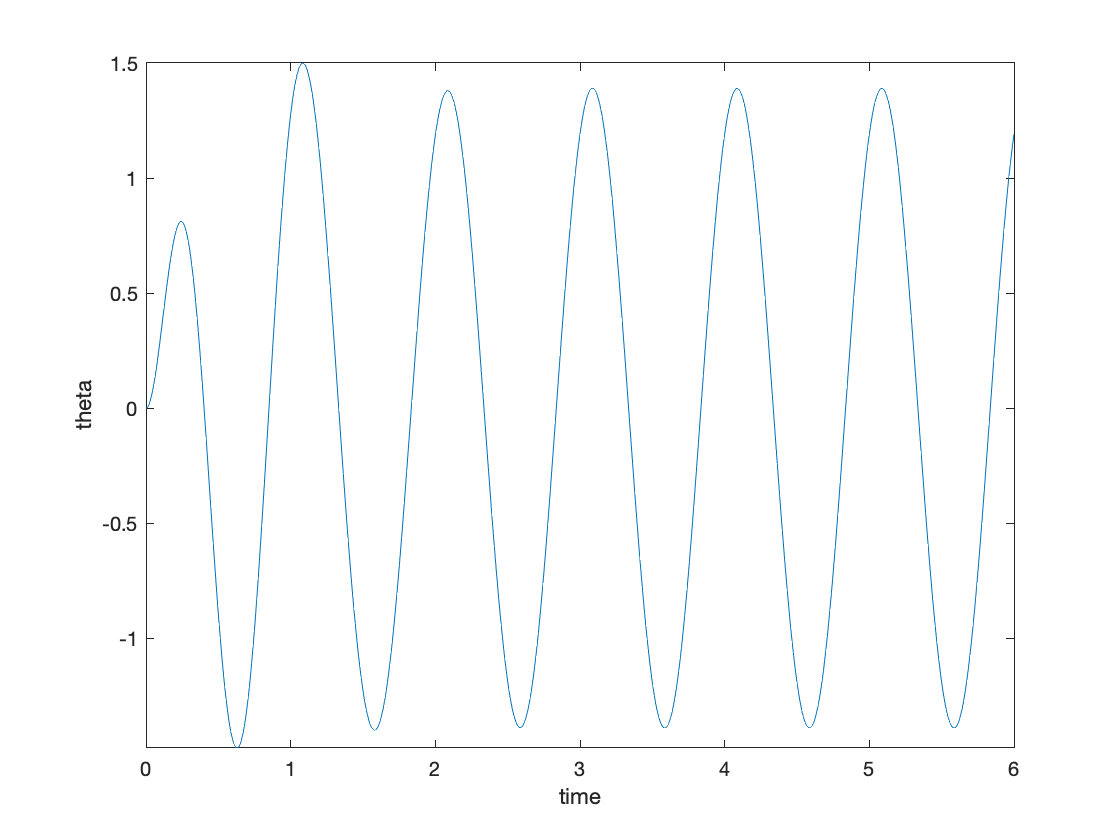

syms tau omega omega_0 gamma phi(t) beta 

dphi = diff(phi, t);
ddphi = diff(phi, t, 2);
equ = ddphi + 2*beta*dphi + omega_0^2*sin(phi) == gamma*omega_0^2*cos(omega*t);
% since gamma << 1, we expect phi to remain small at all times, 
% so sin(phi) ~= phi
equ = subs(equ, sin(phi), phi);

% Replacing parameters with simple values
tau = 1;
old = [omega, omega_0, beta, gamma];
omega = (2*pi)/tau;
omega_0 = 1.5*omega;
beta = omega_0/4;
gamma = 0.9; 
new = [omega, omega_0, beta, gamma];
equ = subs(equ, old, new);

conds = [dphi(0) == 0, phi(0) == 0];
q = dsolve(equ, conds);
% Plotting first 6 seconds of motion
fplot(q, [0,6])
xlabel("time")
ylabel("theta")


$$\sin \phi \approx \phi-\frac{1}{6} \phi^{3}$$
     
$$\to$$
      
$$\ddot{\phi}+2 \beta \dot{\phi}+\omega_{\circ}^{2}\left(\phi-\frac{1}{6} \phi^{3}\right)=\gamma \omega_{\circ}^{2} \cos \omega t$$


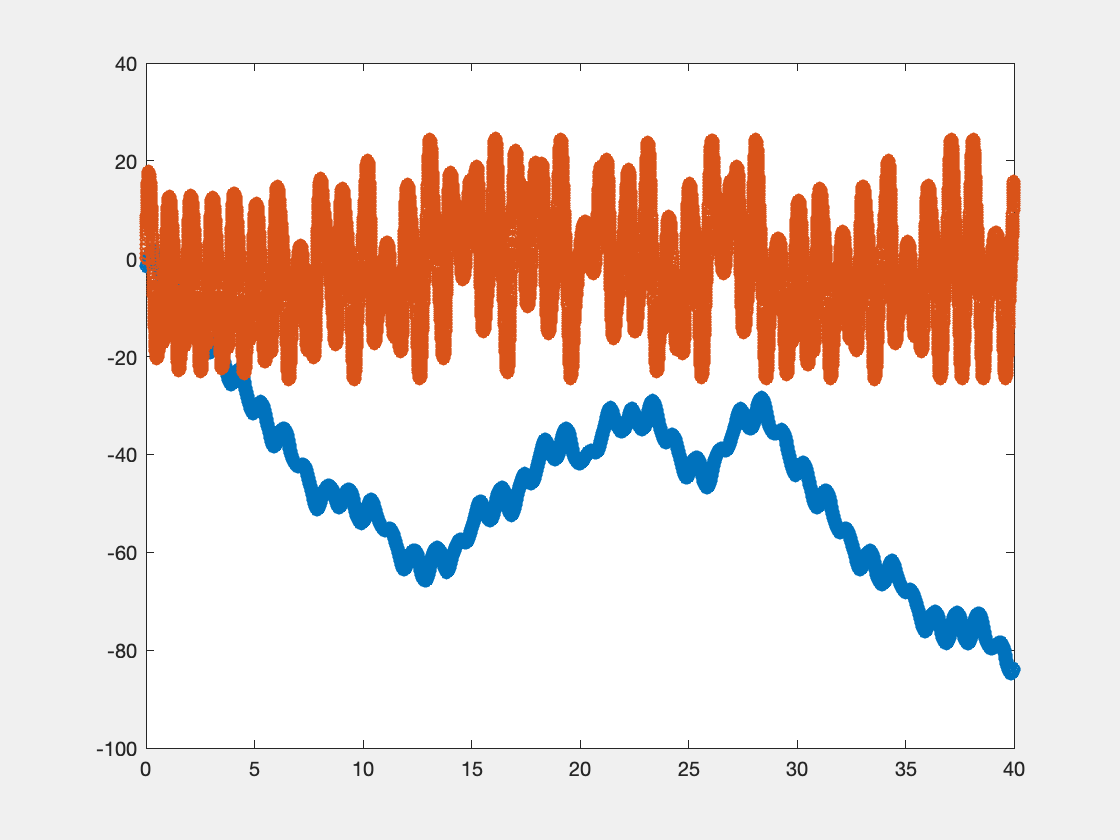

syms tau omega omega_0 gamma phi(t) beta 

dphi = diff(phi, t);
ddphi = diff(phi, t, 2);
equ = ddphi + 2*beta*dphi + omega_0^2*sin(phi) == gamma*omega_0^2*cos(omega*t);
%equ = subs(equ, sin(phi), (phi - (1/6)*phi^3));

% Replacing parameters with values
tau = 1;
old = [omega, omega_0, beta, gamma];
omega = (2*pi)/tau;
omega_0 = 1.5*omega;
beta = omega_0/4;
gamma = 1.503; % drive strengh controls how chaotic it is
new = [omega, omega_0, beta, gamma];
equ = subs(equ, old, new);

% Convert it to set of first order DE's
[V] = odeToVectorField(equ);
M = matlabFunction(V,'vars',{'t','Y'});
tspan = [0 40];
yInit = [-pi/2 0];
% Since it's a super stiff ode, we increase the tolerances
options = odeset('RelTol',1e-6,'AbsTol',1e-5,'Stats','off','OutputFcn',@odeplot);
[t, y] = ode23tb(M,tspan,yInit, options);

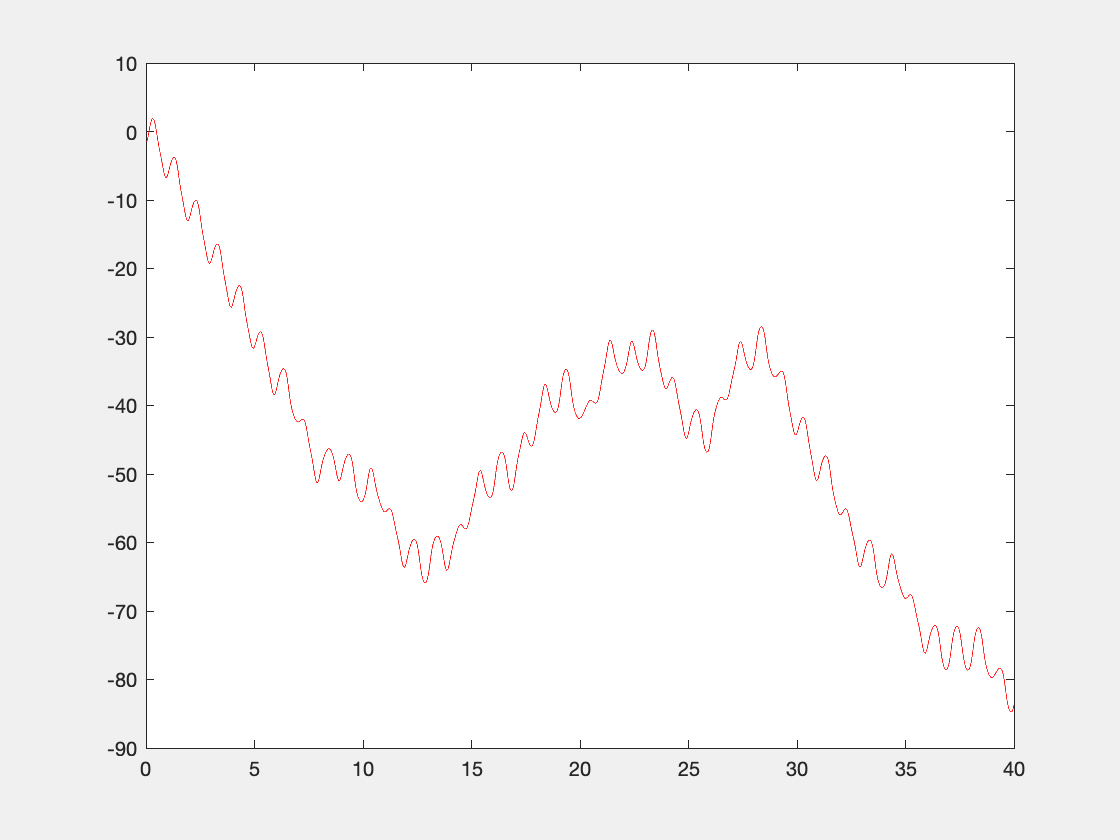

plot(t,y(:,1), '-r')


% hold on
% yInit2 = [-pi/2.00001 0];
% [t, y] = ode23tb(M,tspan,yInit2, options);
% plot(t,y(:,1), '-b')


